clear all
close all
clc



addpath("/Users/Jameskyle/Desktop/CMU/24-775 Bioinspired Robot Design and Experimentation/AcroBOT/Dynamics_HW12/Hardware Data");

fileName = "Hardware Data/Test_7"

fileName = "Hardware Data/Test_7"

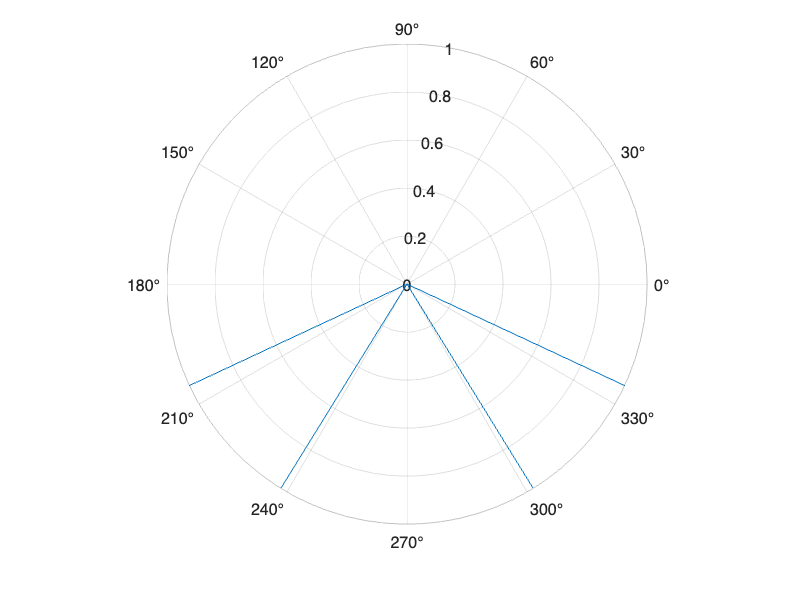



data = readmatrix(fileName,"NumHeaderLines",2);

alpha = data(1,1);
beta = data(1,2);
gamma = data(1,3);
% 
alpha = 45;
beta = 245;
gamma = 33.3;

arch_region = [beta; beta - gamma] + 90;
hollow_region = [90 + (270-beta+gamma); 90 + (270 - beta)] + 90;

figure();
polarplot([0 hollow_region(1)*pi/180 ...
    0 hollow_region(2)*pi/180 ...
    0 arch_region(1)*pi/180 ...
    0 arch_region(2)*pi/180],[0 1 0 1 0 1 0 1])

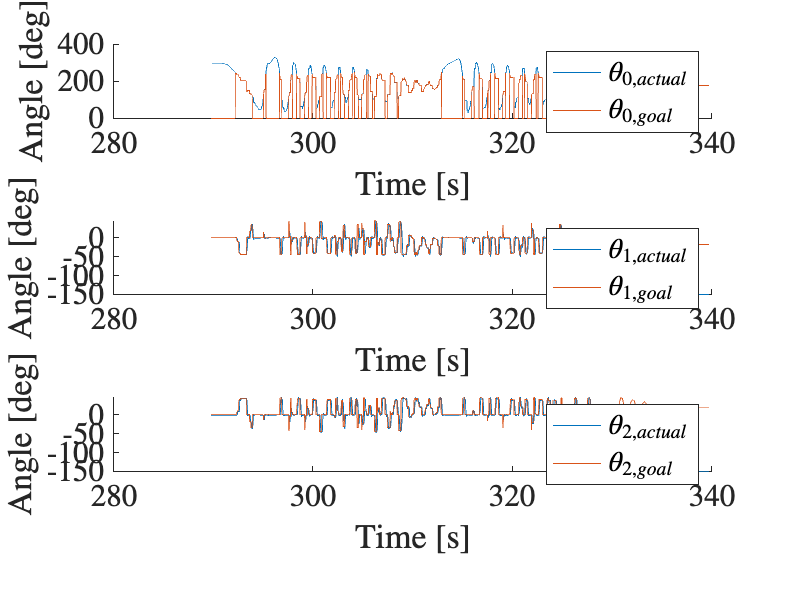



data = readmatrix(fileName,"NumHeaderLines",5);

time = data(:,1);
th0_actual = data(:,2);
th0_goal = data(:,3);
th1_actual = data(:,4);
th1_goal = data(:,5);
th2_actual = data(:,6);
th2_goal = data(:,7);
current = data(:,8);


figure();
subplot(3,1,1);
hold on;
plot(time,th0_actual,"DisplayName","$\theta_{0,actual}$");
plot(time,th0_goal,"DisplayName","$\theta_{0,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

subplot(3,1,2);
hold on;
plot(time,th1_actual,"DisplayName","$\theta_{1,actual}$");
plot(time,th1_goal,"DisplayName","$\theta_{1,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

subplot(3,1,3);
hold on;
plot(time,th2_actual,"DisplayName","$\theta_{2,actual}$");
plot(time,th2_goal,"DisplayName","$\theta_{2,goal}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");

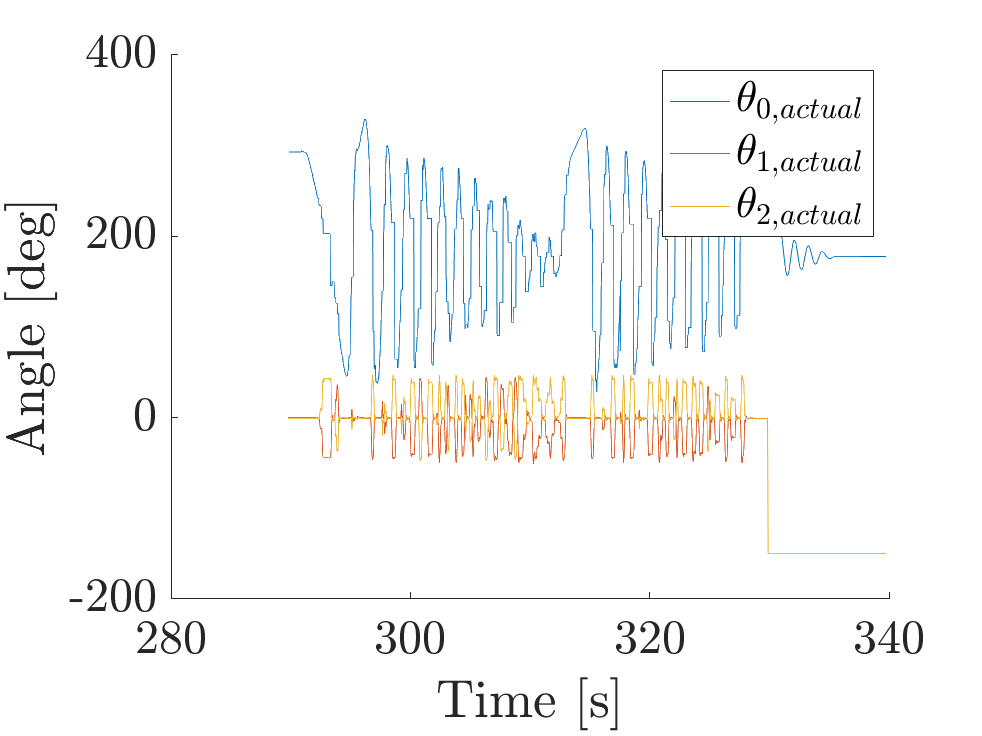







figure();
hold on;
plot(time,th0_actual,"DisplayName","$\theta_{0,actual}$");
plot(time,th1_actual,"DisplayName","$\theta_{1,actual}$");
plot(time,th2_actual,"DisplayName","$\theta_{2,actual}$");
hold off;
legend("Interpreter","latex");
ylabel("Angle [deg]");
xlabel("Time [s]");